## Radiance to Irradiance

The oiCompute() function converts scene radiance into optical image irradiance.  

We show the impact of optical blurring with ideal (diffraction-limited) optics: one example with f/# 2.8 and a second time with f/# 8.0.  Notice the mapping from scene luminance in $cd/m^2$(nits) into sensor irradiance (lux).

## Create the scene

First, create a simple scene with some edges and colors.  Se set the field of view to be small to show the blurring more clearly.

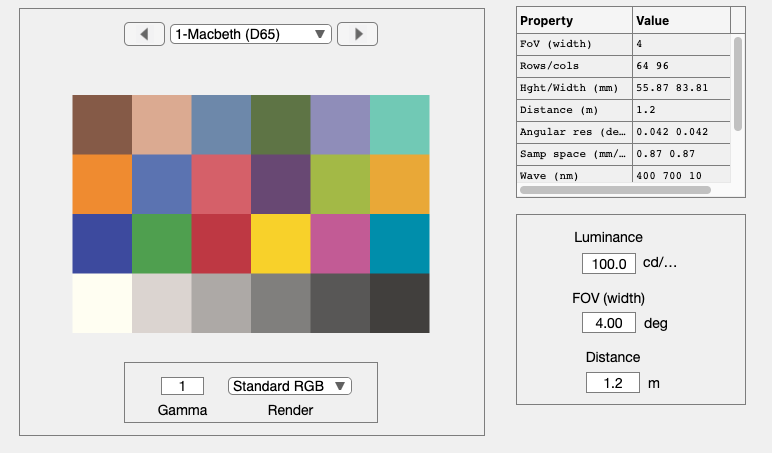

ieInit;
scene = sceneCreate;
scene = sceneSet(scene,'fov',4);
sceneWindow(scene);

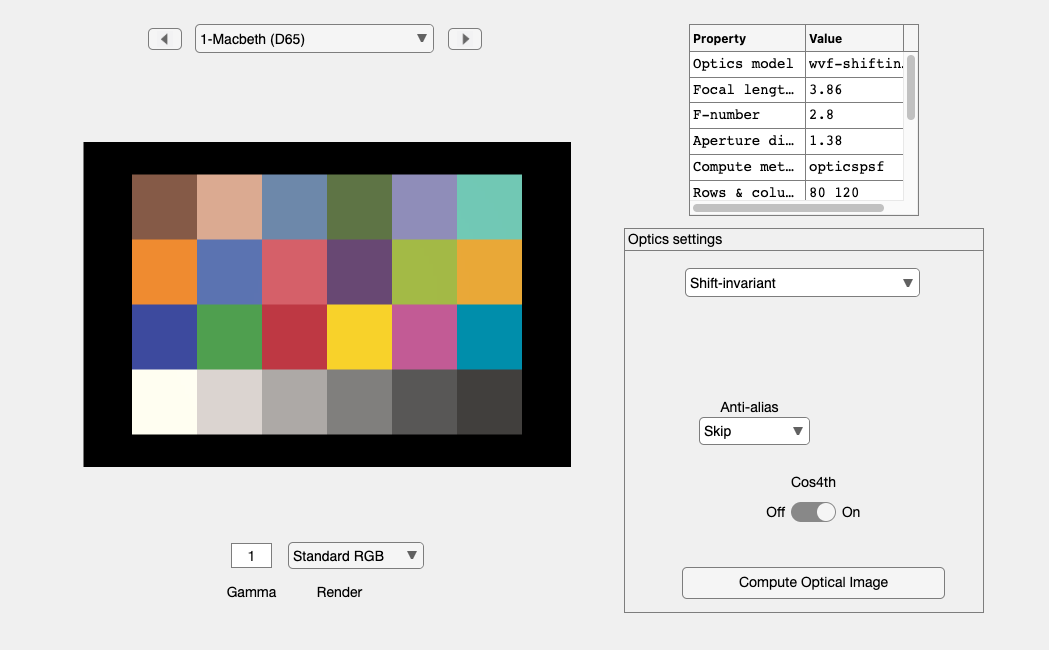


oi = oiCreate('wvf');
oi = oiSet(oi,'optics fnumber',2.8);
oi = oiCompute(oi,scene);
oiWindow(oi);

## Radiance and irradiance plots

First the scene luminance in $\frac{\mathrm{cd}}{m^2 }$.

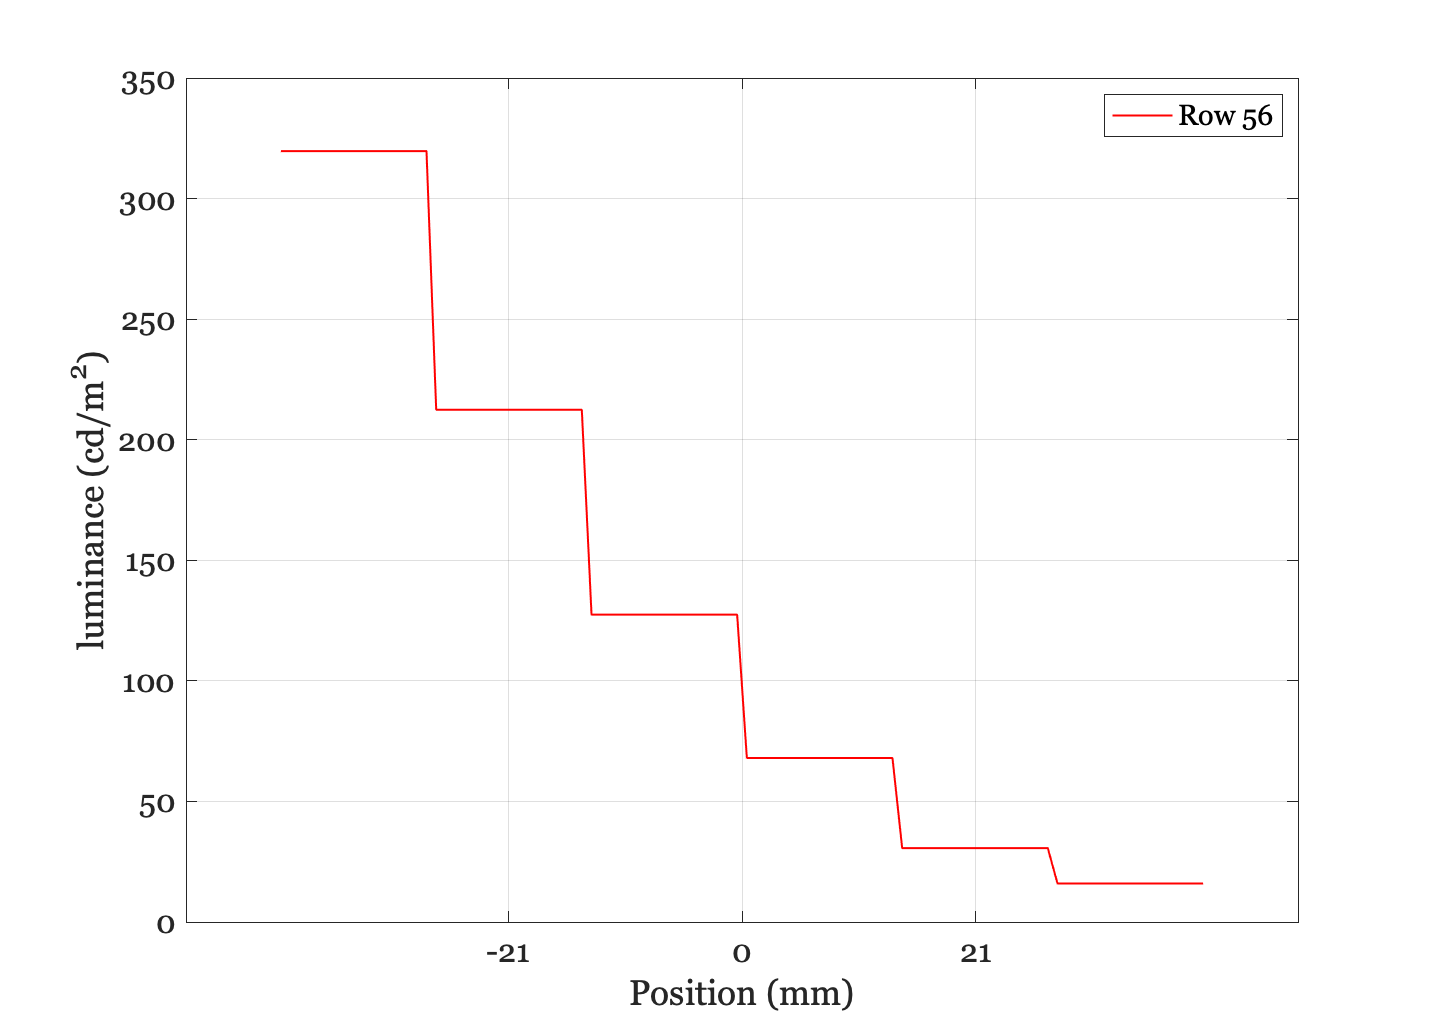

scenePlot(scene,'luminance hline',[1,56]); drawnow;

Here are the aperture diameter, focal length, and illuminance plot in millimeters.  Note how the x-axis scale changes from the scene (mm) to the irradiance at the sensor surface (microns).  This spatial scale transformation arises from the geometry of the focal length and distance to the scene.

fprintf('Aperture %.3f mm\n',oiGet(oi,'optics aperture diameter','mm'))

Aperture 1.380 mm


fprintf('Focal length %.3f mm\n',oiGet(oi,'optics focal length','mm'))

Focal length 3.863 mm


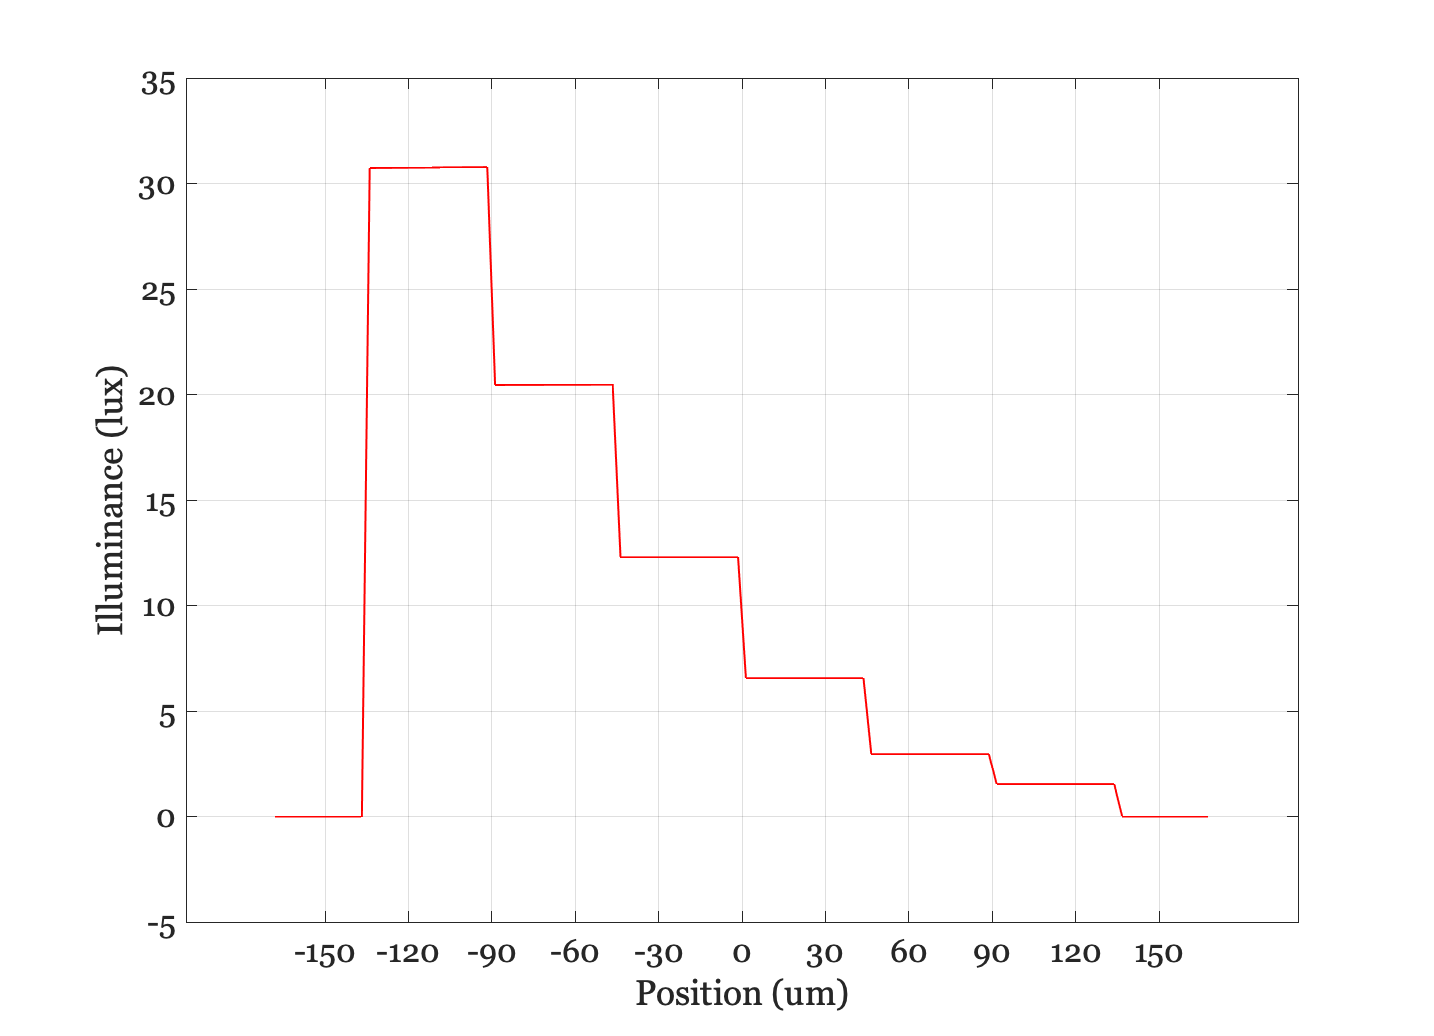

uData = oiPlot(oi,'illuminance hline',[1,72]); drawnow;

## Change the f/# and re-run

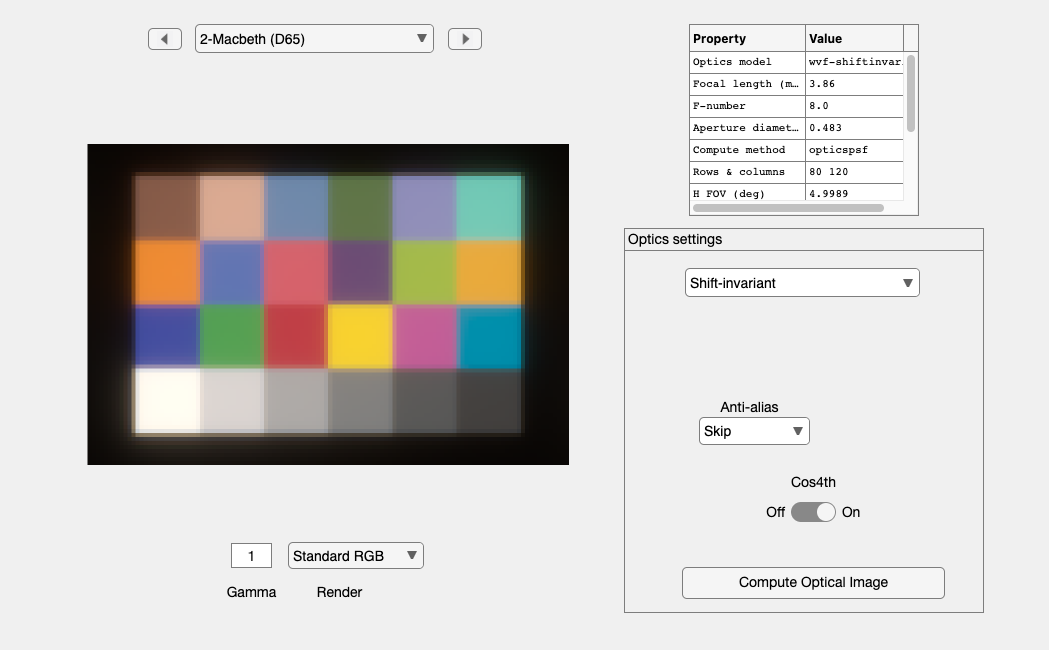

oi = oiSet(oi,'optics fnumber',8);
oi = oiCompute(oi,scene);
oiWindow(oi);

Notice that the illuminance is lower when the f/# is higher.  Here are the aperture diameter, focal length, and the illuminance plot.

fprintf('Aperture %.3f mm\n',oiGet(oi,'optics aperture diameter','mm'))

Aperture 0.483 mm


fprintf('Focal length %.3f mm\n',oiGet(oi,'optics focal length','mm'))

Focal length 3.863 mm


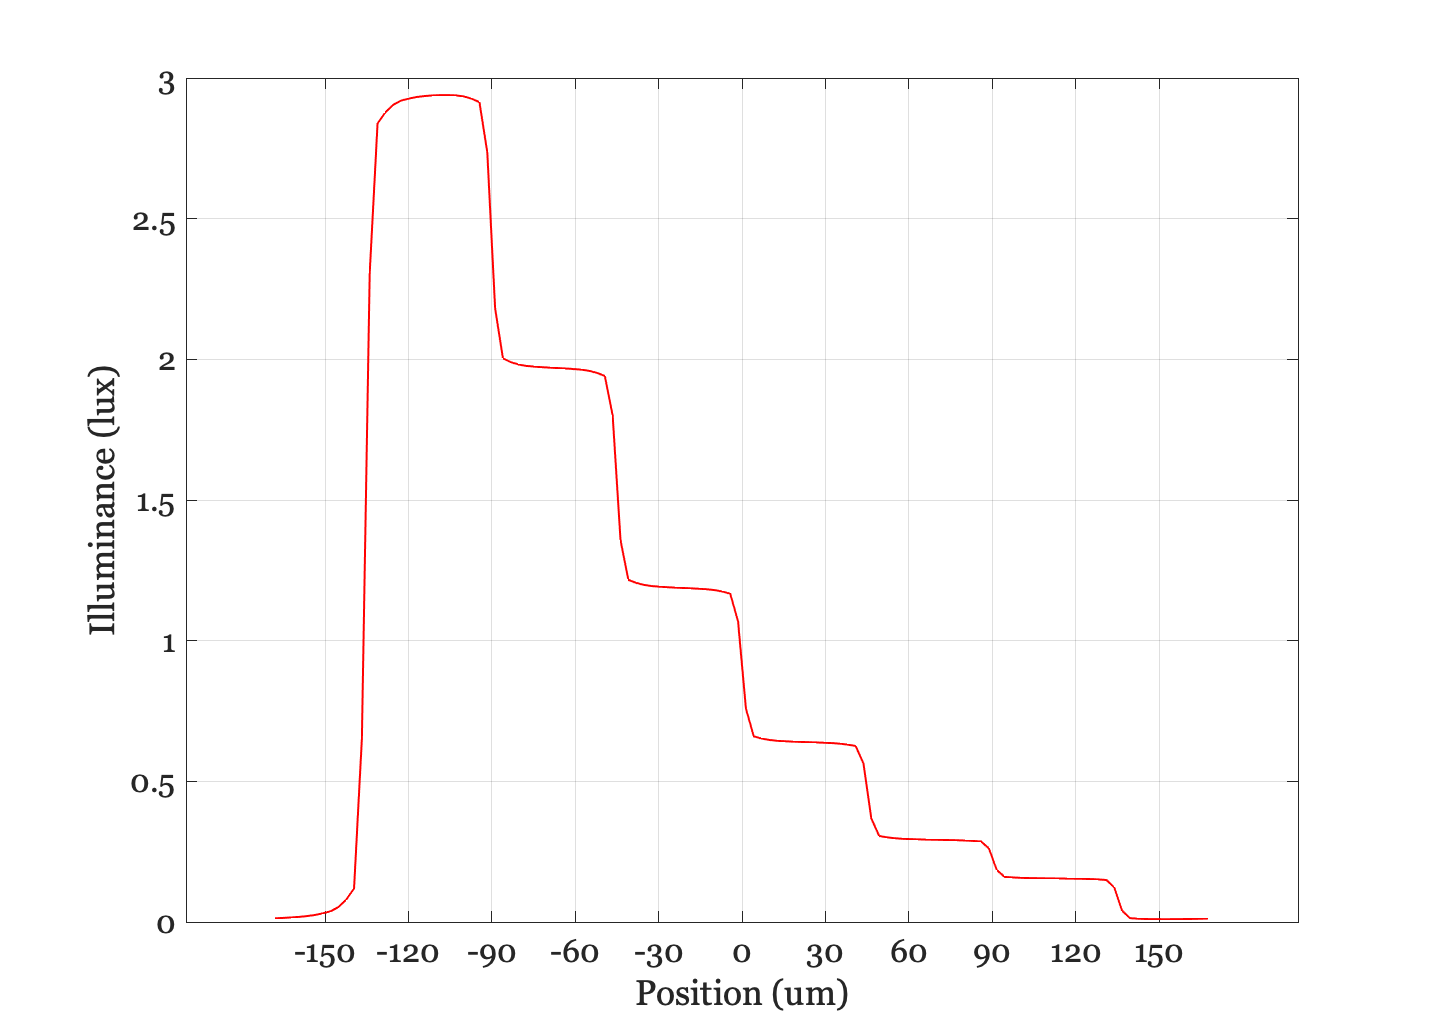

uData2 = oiPlot(oi,'illuminance hline',[1 72]);

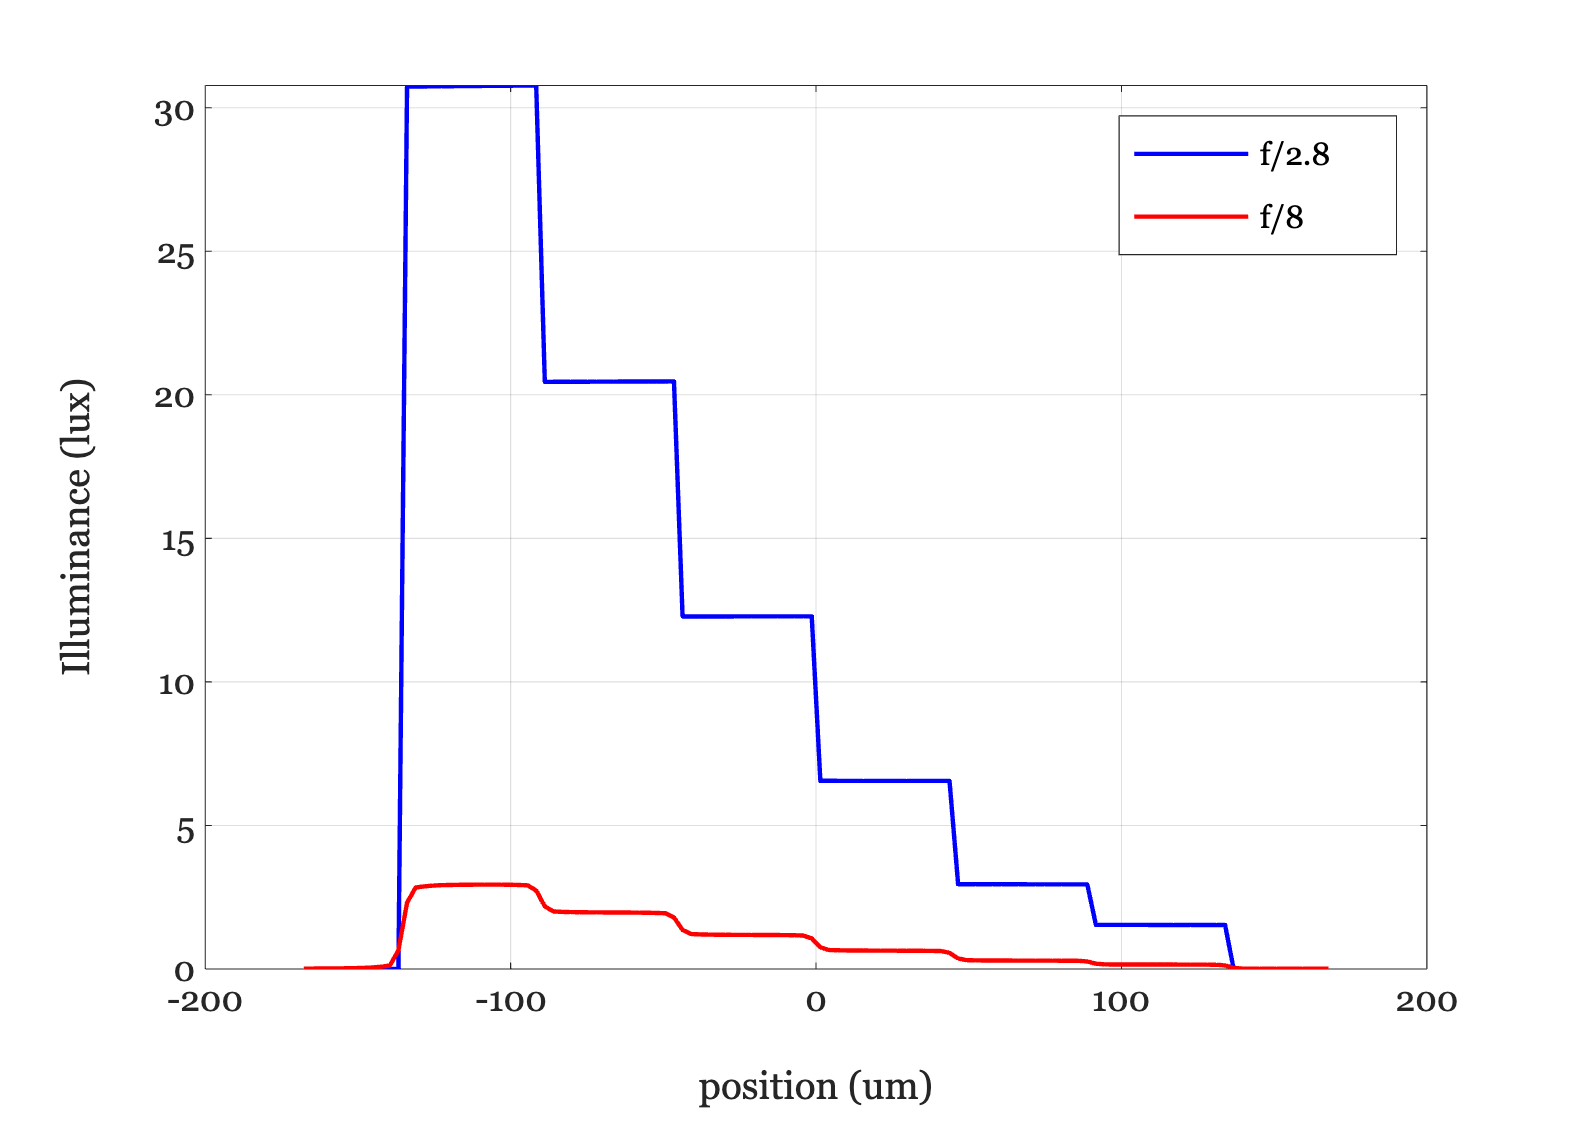

ieNewGraphWin;
p = plot(uData.pos,uData.data,'b',...
    uData2.pos,uData2.data,'r-',...
    'linewidth',2);
legend({'f/2.8','f/8'})
grid on; xlabel('position (um)'); ylabel('Illuminance (lux)')